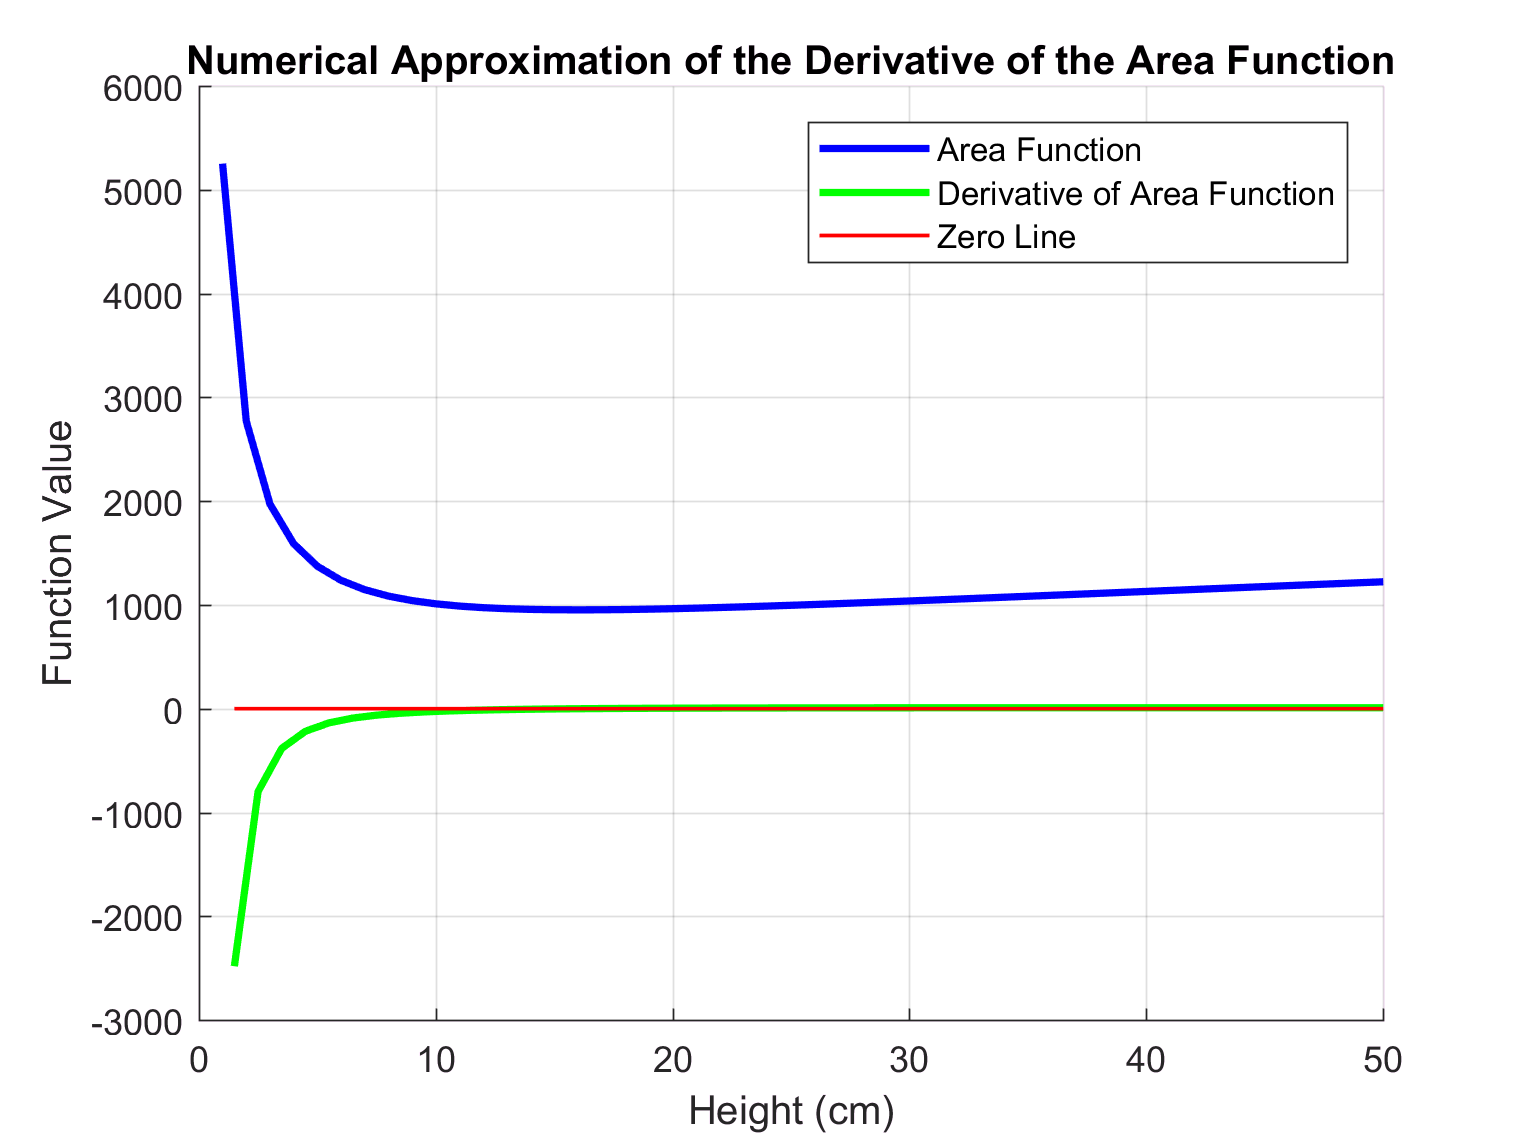

% Exercise
close all; clear all;
h = linspace(1, 1000, 1E3); %define h vector
r = sqrt(2000./(pi.*h)); %define r using volume formula
area = 8*(r.^2) + (2*(pi).*r.*h); %define area equations
area_diff = diff(area)./diff(h);
x = []; %Plot
for i = 1:(length(h)-1)
    x = [x (h(i)+h(i+1))/2];
end
zero(1:length(h)-1) = 0; hold on; grid on;
plot(h, area, '-b', 'LineWidth', 2);
plot(x, area_diff, '-g', 'LineWidth', 2);
plot(x, zero, '-r', 'LineWidth', 1);
title('Numerical Approximation of the Derivative of the Area Function');
xlabel('Height (cm)'); ylabel('Function Value'); xlim([0 50]);
legend('Area Function','Derivative of Area Function', 'Zero Line');

height = 16.08; %height value is the intersection point of the green line
    %with the zero line (where slope of area function is zero for min/max)
radius = sqrt(2000./(pi.*height));
%Answer: height = 16.08 cm // radius = 6.29 cm
